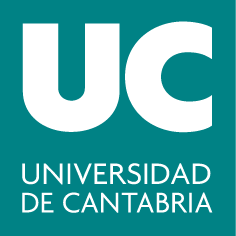

#### ***Grado en Ingeniería Química***

## **G320: Álgebra**

# **Práctica 8: Espacio euclídeo (I)**

*Rodrigo García Manzanas (rodrigo.manzanas@unican.es)*

*Valvanuz Fernández Quiruelas (valvanuz.fernandez@unican.es)*

**Objetivos**

- Operar con productos escalares en MATLAB

- Obtener el complemento ortogonal de un subespacio dado

- Calcular bases ortogonales (y ortonormales)

- Calcular y utilizar la matriz de proyección sobre un cierto subespacio

**Producto escalar**

En MATLAB, se puede calcular el producto escalar usual de $\mathbb{R}^n$ con la función *dot*. Por ejemplo, en $\mathbb{R}^3$, el producto escalar de los vectores $\vec{u}=(4,0,3)$ y $\vec{v}=(1,-2,3)$ se obtendría así:

u = [4 0 3]'; % vector u
v = [1 -2 3]';  % vector v
dot(u, v)  % producto escalar usual 

Si estamos trabajando con productos escalares que impliquen el cálculo de integrales, debemos saber que la función *int* de MATLAB se utiliza para el cálculo integral (en modo simbólico). Por ejemplo, si quisiéramos calcular $\int_{0}^{1} x^2 dx$, haríamos:

syms x real  % hay que definir la variable simbólica sobre la que integro
int(x^2, 0, 1)  % hay que que darle a 'int' la función a integrar y los límites de integración

La norma o módulo de un vector puede calcularse fácilmente con la función *norm. *Eso sí, *norm* considera el producto escalar usual, por lo que, si estuviésemos trabajando con otro tipo de producto, habría que calcularla "a mano".

norm(u)  % norma del vector u (considerando el producto escalar usual)
sqrt(dot(u, u))  % comprobamos que obtenemos el mismo resultado

Por tanto, normalizar el vector$\vec{u}$ sería tan fácil como:

u_norm = u/norm(u)  % vector normalizado
norm(u_norm)  % efectivamente, el módulo del vector normalizado es 1

**Cálculo de subespacios ortogonales**

Sea $S$ un subespacio de $\mathbb{R}^4$ dado en su forma paramétrica, $S = \lbrace (\alpha, \alpha, \beta, \beta): \alpha, \beta \in \mathbb{R}\rbrace$. Para encontrar el complemento ortogonal (o simplemente ortogonal) de $S$, $S^
\perp$, tendremos que buscar todos los vectores ortogonales a $S$. Partiremos, para ello, de una base de $S$:

baseS = [1 1 0 0; 0 0 1 1]'  % base de S

$S^\perp$ estará formado por los vectores $(x,y,z,t)$ que satisfagan las siguientes ecuaciones:


$$(1,1,0,0) \cdot (x,y,z,t)=0 \\ (0,0,1,1) \cdot (x,y,z,t)=0$$


Si consideramos el producto escalar usual, esto se puede escribir en forma matricial como:


$$\left\lbrack \begin{array}{cccc}
1 & 1 & 0 & 0\\
0 & 0 & 1 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
y\\
z\\
t
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$$


Por tanto, para hallar una base de $S^\perp$ bastaría con resolver el sistema homogéneo que tiene como matriz de coeficientes los vectores de la base de $S$ (colocados por filas):

baseS_ortog = null(baseS', 'r')  % base de S_ortog: {(-1,1,0,0), (0,0,-1,1)}

Como vemos, la base de $S^\perp$ está compuesta por dos vectores, por lo que $dim(S^\perp)=2$. Esto era de esperar, puesto que ya vimos que $dim(S)=2$, y sabemos que, por ser complementarios, $dim(S)+dim(S^\perp)=4$. Efectivamente:

rank([baseS baseS_ortog])  % la unión de la base de S y la base de S_ortog forman una base del espacio total, R4

Podemos comprobar fácilmente que $S$ y $S^\perp$ son en efecto ortogonales viendo que el producto escalar de los vectores de sus bases (las combinaciones de todos con todos) es $0$:

% Comprobación ORTOGONALIDAD
dot(baseS(:,1), baseS_ortog(:,1))
dot(baseS(:,1), baseS_ortog(:,2))
dot(baseS(:,2), baseS_ortog(:,1))
dot(baseS(:,2), baseS_ortog(:,2))

**Cálculo de bases ortogonales (y ortonormales)**

Si el subespacio viene dado por sus ecuaciones implícitas, la función *null *(sin el argumento de entrada opcional *'r'*) actuando sobre la matriz de los coeficientes nos devuelve una base ortonormal. Por ejemplo, para el subespacio $S = \lbrace  (x,y,z,t,r): 2x-y-z=0, 2x-3z+t=0\rbrace$ de $\mathbb{R}^5$:

coefImpS = [2 -1 -1 0 0; 2 0 -3 1 0];  % coefs. eqs. implícitas S
baseS = null(coefImpS, 'r')  % base de S
dot(baseS(:,1), baseS(:,2))  % vemos que NO es ORTOGONAL --> NO es ORTONORMAL
baseortonS = null(coefImpS)  % base ORTONORMAL de S

% Comprobación ORTOGONALIDAD
dot(baseortonS(:,1), baseortonS(:,2))
dot(baseortonS(:,1), baseortonS(:,3))
dot(baseortonS(:,2), baseortonS(:,3))
% Comprobación ORTONORMALIDAD 
norm(baseortonS(:,1))
norm(baseortonS(:,2))
norm(baseortonS(:,3))

Siempre que estemos trabajando con el producto escalar usual se puede obtener fácilmente una base ortonormal de un subespacio partiendo de una base cualquiera (por ejemplo, no ortogonal) del mismo. Para ello utilizaremos la función *orth*, que ortonormaliza los vectores columna de una matriz cualquiera. Por ejemplo, siguiendo con el mismo subespacio de $\mathbb{R}^5$ del ejemplo anterior, $S = \lbrace (1.5\alpha -0.5\beta, 2\alpha - \beta, \alpha, 0, \gamma): \alpha, \beta, \gamma \in \mathbb{R}\rbrace$:

baseS = [1.5 2 1 0 0; -0.5 -1 0 1 0; 0 0 0 0 1]';  % base NO ORTONORMAL de S
baseorton2S = orth(baseS)  % base ORTONORMAL de S

Fíjate que la base devuelta por *orth *es distinta a la que se obtiene con *null, *pero igual de válida.

% Comprobación ORTOGONALIDAD
dot(baseorton2S(:,1), baseorton2S(:,2))
dot(baseorton2S(:,1), baseorton2S(:,3))
dot(baseorton2S(:,2), baseorton2S(:,3))
% Comprobación ORTONORMALIDAD
norm(baseorton2S(:,1))
norm(baseorton2S(:,2))
norm(baseorton2S(:,3))

***Nota:*** Si los vectores columna que se le pasan a *orth* no fuesen linealmente independientes, la propia función se encarga de eliminar los que sean dependientes y ortonormaliza el resto.  

**Matriz de proyección**

La matriz de proyección sobre un subespacio $S$ se obtiene como $P_S=B_S(B_{S}^{t}B_S)^_{-1}B_{S}^t$, donde $B_S$ es una matriz que contiene en sus columnas los vectores de una base (cualquiera, no tiene por qué ser ortogonal/ortonormal) de $S$. Por tanto, para hallar la matriz de proyección sobre un subespacio $S = <(2,-1,1), (-1,2,1)>$ de $\mathbb{R}^3$:

baseS = [2 -1 1; -1 2 1]';  % base de S (es un sist. gen. y los vectores son L.I.). 
dot(baseS(:,1), baseS(:,2))  % vemos que esta base NO es ortogonal
PS = baseS*inv(baseS'*baseS)*baseS'  % matriz de proyección sobre S

Podemos ver que $P_S$ cumple las tres propiedades que ha de cumplir toda matriz de proyección:

% 1) Es cuadrada
% 2) Es simétrica
% 3) Es idempotente (Ps=Ps^2)
PS - PS^2  

Acabamos de ver que $P_S$ es la matriz de proyección sobre el subespacio cuya base es $\lbrace (2,-1,1), (-1,2,1) \rbrace$. Una vez hemos calculado $P_S$, sería inmediato proyectar cualquier vector $\vec{v}$ sobre $S$; tan sólo habría que aplicarle la matriz $P_s$ ( es decir, multiplicar $P_S$ por $\vec{v}$). Por ejemplo, para proyectar ortogonalmente el vector $(3,4,5)$ sobre $S$:

v = [3 4 5]';  % vector a proyectar
PS*v  % proyección de v sobre S

#### Ejercicios propuestos

**Ejercicio 1:**

En $\mathbb{C}[0,1]$, sean las funciones $f(x)=x^2$ y $g(x)=x+1$ y el producto escalar definido como $f \cdot g = \int_{0}^{1} f(x)g(x)dx$: 

- *a)* Normaliza $f$ y $g$. Comprueba que tus resultados son correctos.

- *b)* Calcula la distancia y ángulo que existe entre $f$ y $g$.

**Ejercicio 2:**

En $\mathbb{M}_{3 \times 3}$, con el producto escalar $A \cdot B = tr(A^tB)$, normaliza las siguientes matrices:


$$A=\left\lbrack \begin{array}{ccc}
1 & 2 & 0\\
0 & -2 & 1\\
-1 & 0 & 1
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;B=\left\lbrack \begin{array}{ccc}
1 & 0 & -1\\
2 & 0 & 2\\
1 & 2 & 3
\end{array}\right\rbrack$$


Comprueba que tus resultados son correctos.

*Nota*: La traza de una matriz es la suma de todos los elementos en su diagonal principal. En MATLAB, se calcula directamente con la función *trace*.

**Ejercicio 3:**

En $\mathbb{R}^4$, obtén una base del complemento ortogonal del subespacio $S=\lbrace (\alpha, 0, 2\alpha, \alpha): \alpha \in \mathbb{R}\rbrace$. Verifica que $S^\perp$ es ortogonal a $S$ y que $S$ y $S^\perp$ son subespacios complementarios/suplementarios.

**Ejercicio 4:**

En $\mathbb{R}^3$, proyecta ortogonalmente el vector $\vec{v} = (3,2,2)$ sobre el subespacio $S=<(2,0,1),(0,3,-1),(2,3,0)>$ utilizando la matriz de proyección. Calcula dicha matriz partiendo de dos bases de $S$ distintas, una de ellas ortonormal y la otra no. ¿Qué sucede?

**Ejercicio 5:**

Utilizando matrices de proyección, calcula la proyección ortogonal del vector $$\vec{v} = (3, 4, 5)$$ sobre el subpespacio $S : \lbrace x-y+z=0 \rbrace$ de $\mathbb{R}^3$ y sobre $S^\perp$. Comprueba que ambas proyecciones son ortogonales entre sí y que $\vec{v}$ puede expresarse como la suma de ambas. ¿Qué pasa si sumas la matriz de proyección sobre $S$ y la matriz de proyección sobre $S^\perp$?